# Quarter-car Suspension Model

Ms=250;
Mus=30;
Kus=150000;
Ks=15000;
Bs=1000;


$$\dot{x}=Ax+Bu+Ed$$



$$y_m=Cx+n$$



$$z=\left\lbrack \begin{array}{c}
\sqrt{\;Q}x\\
\sqrt{\;R}u
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sqrt{\;Q}\\
\sqrt{\;R}K_{\textrm{sf}} 
\end{array}\right\rbrack x$$


A = [0,1,0,0;
    -Kus/Mus,-Bs/Mus,Ks/Mus,Bs/Mus;
    0,-1,0,1;
    0,Bs/Ms,-Ks/Ms,-Bs/Ms];
Nx = size(A,1);
B = [0;Ms/Mus;0;-1];
Nu = size(B,2);
C = [0,0,1,0];
Ny = size(C,1);
E = [-1;0;0;0];
Nd = size(E,2);

I4 = eye(Nx);
%Q=I4;
%R=eye(Nu);

####  LQR State-Feedback

% Data given in problem
q1 = 50000;
q3 = 5000;
gamma = 1;
r = 0;

% Form (Q,R,S)
% Note that d(x4)/dt = A(4,:) x + B(4)*u
Q = diag([q1 0 q3 0])+ gamma* A(4,:)'*A(4,:);
S = gamma*A(4,:)'*B(4);
R = r + gamma*B(4)^2;

%% LQR State-Feedback
Ksf = lqr(A,B,Q,R,S);


$$T_{d\rightarrow z}=$$



$$\dot{x} =A-{\textrm{BK}}_{\textrm{sf}} x+\textrm{Ed}$$



$$z=\left\lbrack \begin{array}{c}
\sqrt{\;Q}x\\
\sqrt{\;R}u
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sqrt{\;Q}\\
\sqrt{\;R}K_{\textrm{sf}} 
\end{array}\right\rbrack x$$


Qrt = real(sqrtm(Q));
Tsf = ss(A-B*Ksf,E,[Qrt;sqrtm(R)*Ksf],[]);

#### Observer State-Feedback


$$\dot{x}=Ax+Bu+Ed$$



$$y_m=Cx+n$$



$$\dot{\hat{x}}=A\hat{x}+Bu+L(y_m-C\hat{x})$$



$$u=K_{sf}\hat{x}$$



$$z=\left\lbrack \begin{array}{c}
\sqrt{\;Q}x\\
\sqrt{\;R}u
\end{array}\right\rbrack$$


%% Kalman Filter Gain
V = 7e-4;   % Covariance for process noise d, (m/s)^2
W = 1e-8;   % Covariance for sensor noise n, m^2

L = lqe(A,E,C,V,W);

%% Observer State-Feedback


$$T_{d\rightarrow z}=$$



$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & -{\textrm{BK}}_{\textrm{sf}} \\
\textrm{LC} & A-{\textrm{BK}}_{\textrm{sf}} -\textrm{LC}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
E\\
0
\end{array}\right\rbrack d$$



$$z=\left\lbrack \begin{array}{cc}
\sqrt{\;Q} & 0\\
0 & \sqrt{\;R}K_{\textrm{sf}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$$


Aosf = [A -B*Ksf; L*C A-B*Ksf-L*C];
Bosf = [E; zeros(4,1)];
Cosf = [Qrt,zeros(4,4);zeros(1,4),sqrtm(R)*Ksf];
Tosf = ss(Aosf,Bosf,Cosf,0);

#### H2/Hinf problems


$$\dot{x} =\textrm{Ax}+\left\lbrack \begin{array}{cc}
E & B
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d\\
u
\end{array}\right\rbrack$$



$$z=\left\lbrack \begin{array}{c}
\sqrt{\;Q}x\\
\sqrt{\;R}u
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sqrt{\;Q}\\
0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{cc}
0 & 0\\
0 & \sqrt{R}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d\\
u
\end{array}\right\rbrack$$



$$y=\left\lbrack \begin{array}{c}
x\\
d
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
I\\
0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{cc}
0 & 0\\
I & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
d\\
u
\end{array}\right\rbrack$$


Cz = [Qrt; zeros(Nu,Nx)];

Dzd = [zeros(Nx,Nd); zeros(Nu,Nd)];
Dzu = [zeros(Nx,Nu); sqrtm(R)];
Dz = [Dzd Dzu];

% Strictly Causal: y = x
% Cy = I4;
% Dy = zeros(Nx,Nx+Nu);
% Ny = Nx;

% Casual: y = [x; d]
Cy = [I4; zeros(Nd,Nx)];
Dy = [zeros(Nx,Nd+Nu); eye(Nd) zeros(Nd,Nu)];
Ny = Nx+Nd;

%Pic = ss(A,[E B],[Cz;Cy], [Dz;Dy],1);
Pic = ss(A,[E B],[Cz;Cy], [Dz;Dy]);

%% Solve H2/Hinf problems

% K2 is a dynamic controller. The code solves for the optimal
% state-feedback/observer assuming this is a general problem even if we
% set y=x or y=[x,w]. K2 will be "almost" a static controller if y=x or
% y=[x,w].  The code also returns the exact static gain for the full
%information case y=[x,w] in the field INFO2.KFI. This full-information
% gain and is equal to [-Kx -Kw] where Kx and Kw are computed below.
[K2,CL2,GAM2,INFO2] = h2syn(Pic,Ny,Nu);
fprintf('\nOptimal H2:  ||CL||_2 = %4.3f \t ||CL||_inf = %4.3f',...
    norm(CL2,2), norm(CL2,inf) )


Optimal H2:  ||CL||_2 = 48.466 	 ||CL||_inf = 13.415


% Kinf is also a dynamic controller. We can use HINFFI to solve the
% full information problem corresponding to y=[x;w].
[Kinf,CLinf,GAMinf,INFOinf] = hinfsyn(Pic,Ny,Nu);
fprintf('\nOptimal Hinf:  ||CL||_2 = %4.3f \t ||CL||_inf = %4.3f',...
    norm(CLinf,2), norm(CLinf,inf) )


Optimal Hinf:  ||CL||_2 = 89.859 	 ||CL||_inf = 10.801


% HINFI solves the full information Hinf problem with y=[x;w].  This
% returns the static full information gain Kfi.
%Pfi = ss(A,[E B],Cz, Dz,1);
Pfi = ss(A,[E B],Cz, Dz);
[Kfi,CLfi,GAMfi] = hinffi(Pfi,Nu);
fprintf('\nOptimal Hinf FI:  ||CL||_2 = %4.3f \t ||CL||_inf = %4.3f',...
    norm(CLfi,2), norm(CLfi,inf) )


Optimal Hinf FI:  ||CL||_2 = 89.859 	 ||CL||_inf = 10.801

#### Plot results

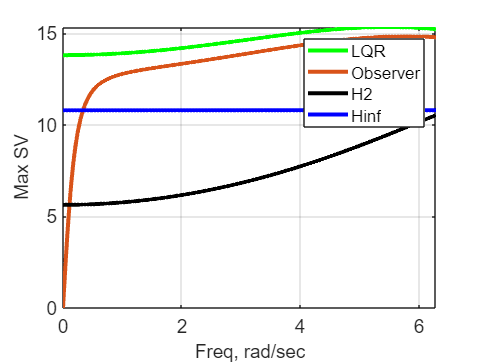

w=linspace(0,2*pi,1e3);
SVsf = sigma(Tsf,w);
SVobs = sigma(Tosf,w);
SV2 = sigma(CL2,w);
SVinf = sigma(CLinf,w);

plot(w,SVsf(1,:),'g',w,SVobs(1,:),w,SV2(1,:),'k',w,SVinf(1,:),'b');
xlim([0, 2*pi]);
xlabel('Freq, rad/sec');
ylabel('Max SV');
grid on;
legend('LQR','Observer','H2','Hinf')
if exist('garyfyFigure','file'), garyfyFigure, end